# **ANALISIS DENAVIT HARTENBERG**

syms theta1 theta2 l1 l2
T01 = trotz(0)

T01 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T12 = trotz(theta1)*transl(l1,0,0)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & l_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & l_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = trotz(theta2)*transl(l2,0,0)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

3 sistemas sobre el mismo plano

Ahora, hallar las matrices para un punto *a* que se alcanza con $\theta_1$y $\theta_2$

T03 = T01*T12*T23

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & l_{1}\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & l_{1}\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

subs(T03, {l1, l2, theta1, theta2},{15, 15, deg2rad(30), deg2rad(30)})

$$ans = \left(\begin{array}{cccc} \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & \frac{15\,\sqrt{3}}{2}+\frac{15}{2}\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0 & \frac{15\,\sqrt{3}}{2}+\frac{15}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

# **CINEMATICA INVERSA**

% Punto a encontrar
syms x y l
syms theta3

Sistema de ecuaciones

E1 = simplify(T03(1,4)) == x

$$E1 = l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\cos\left(\theta_{1}\right)=x$$

E2 = simplify(T03(2,4)) == y

$$E2 = l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+l_{1}\,\sin\left(\theta_{1}\right)=y$$

Para simplificar el procedimiento se asume $l_1$y $l_2$ iguales, en caso de no ser así el resultado más optimo, se debe hacer una traslación en el eje$X$partiendo del resultado obtenido.

- 
$$\theta_3 =\theta_1 +\theta_2$$


E1 = l*(cos(theta3)+cos(theta1)) == x

$$E1 = l\,\left(\cos\left(\theta_{1}\right)+\cos\left(\theta_{3}\right)\right)=x$$

E2 = l*(sin(theta3)+sin(theta1)) == y

$$E2 = l\,\left(\sin\left(\theta_{1}\right)+\sin\left(\theta_{3}\right)\right)=y$$

Suma de cosenos y senos

- 
$$\textrm{Cos}\left(\theta_1 \right)+\textrm{Cos}\left(\theta_2 \right)=2\cdot \textrm{Cos}\left(\frac{\theta_1 +\theta_2 }{2}\right)\cdot \textrm{Cos}\left(\frac{\theta_1 -\theta_2 }{2}\right)$$


- 
$$\textrm{Sen}\left(\theta_1 \right)+\textrm{Sen}\left(\theta_2 \right)=2\cdot \textrm{Sen}\left(\frac{\theta_1 +\theta_2 }{2}\right)\cdot \textrm{Cos}\left(\frac{\theta_1 -\theta_2 }{2}\right)$$


E1 = l*2*cos((theta1+theta3)*.5)*cos((theta1-theta3)/2) == x

$$E1 = 2\,l\,\cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)=x$$

E2 = l*2*sin((theta1+theta3)/2)*cos((theta1-theta3)/2) == y

$$E2 = 2\,l\,\cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)\,\sin\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)=y$$

S1 = theta1 + theta3 == atan2(y,x)*2

$$S1 = \theta_{1}+\theta_{3}=2\,\text{atan2}\left(y,x\right)$$

s1 = (theta1 + theta3)/2;
S2 = cos((theta1-theta3)/2) == x/(2*l*cos(s1))

$$S2 = \cos\left(\frac{\theta_{1}}{2}-\frac{\theta_{3}}{2}\right)=\frac{x}{2\,l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}$$

s2 = x/(2*l*cos(s1))

$$s2 = \frac{x}{2\,l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}$$

S3 = theta1 - theta3 == atan2(sqrt(1-s2^2),s2)

$$S3 = \theta_{1}-\theta_{3}=\text{atan2}\left(2\,\sqrt{1-\frac{x^{2}}{4\,l^{2}\,{\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}^{2}}},\frac{x}{l\,\cos\left(\frac{\theta_{1}}{2}+\frac{\theta_{3}}{2}\right)}\right)$$

- Sabiendo que, $\cos \left(\frac{\theta_1 }{2}-\frac{\theta_3 }{2}\right)=\frac{x}{2\cdot l\cdot \,\cos \left(\textrm{atan2}\left(y,x\right)\right)}$

- 
$$\beta =\theta_1 +\theta_3$$


- 
$$\gamma =\theta_1 -\theta_3$$


- $\theta_1 =\frac{\beta +\gamma }{2}$, con $\theta_1$ se halla $\theta_3$

- 
$$\theta_2 =\theta_3 -\theta_1$$


# TESTEO DE LA SOLUCIÓN

clear l x y theta1 theta2 theta3
format longG
x = 7.8;
y = 21;
l = 15;
beta = 2*atan2(y,x);

    
$$\beta =\theta_1 +\theta_3$$


cost1mt3 = x/(2*l*cos(beta/2));
gamma = 2*atan2(sqrt(1-cost1mt3^2),cost1mt3);

    
$$\gamma =\theta_1 -\theta_3$$


theta1 = (beta+gamma)/2;
theta3 = beta - theta1;
theta2 = theta3 - theta1;
x2 = l*cos(theta1)

x2 =          -5.45266708675023


y2 = l*sin(theta1)

y2 =           13.9738477750787


theta1 = rad2deg(theta1)

theta1 =           111.315984349771


theta2 = rad2deg(theta2)

theta2 =          -83.3848391272155


Resultado esperado, cinematica inversa hallada correctamente

# PERFIL DE POSICION, VELOCIDAD, ACELERACION Y JERK

syms t;
tmin = 0;
tmax = 2*pi;
t_values = linspace(tmin, tmax, 600);
s = 2.5; % Size
r = 3*pi/2; % rotation
leafs = 3;
roundness = 3
l = 20; % Arms long
Ox = 9; % Offset x
Oy = 23; % Offset y
x = s*(cos(leafs*t + r) + roundness)*cos(t)+ Ox;
y = s*(cos(leafs*t + r) + roundness)*sin(t)+ Oy;
b = atan2(y,x)*2;
gamma = 2*atan2(sqrt(1-(x/(2*l*cos(b/2)))^2),x/(2*l*cos(b/2)));
theta1 = (b + gamma)/2;

#### Pos**ición **$\theta_1$

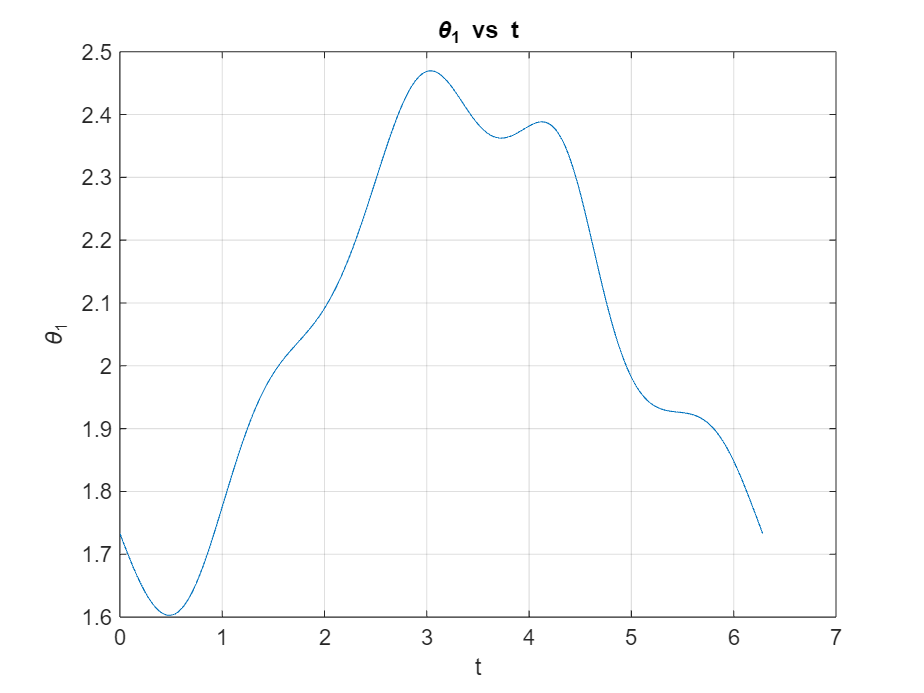

theta1_values = double(subs(theta1, t, t_values));
plot(t_values, theta1_values);
xlabel('t');
ylabel('\theta_1');
title('\theta_1 vs t');
grid on;

**Posición **$\theta_2$

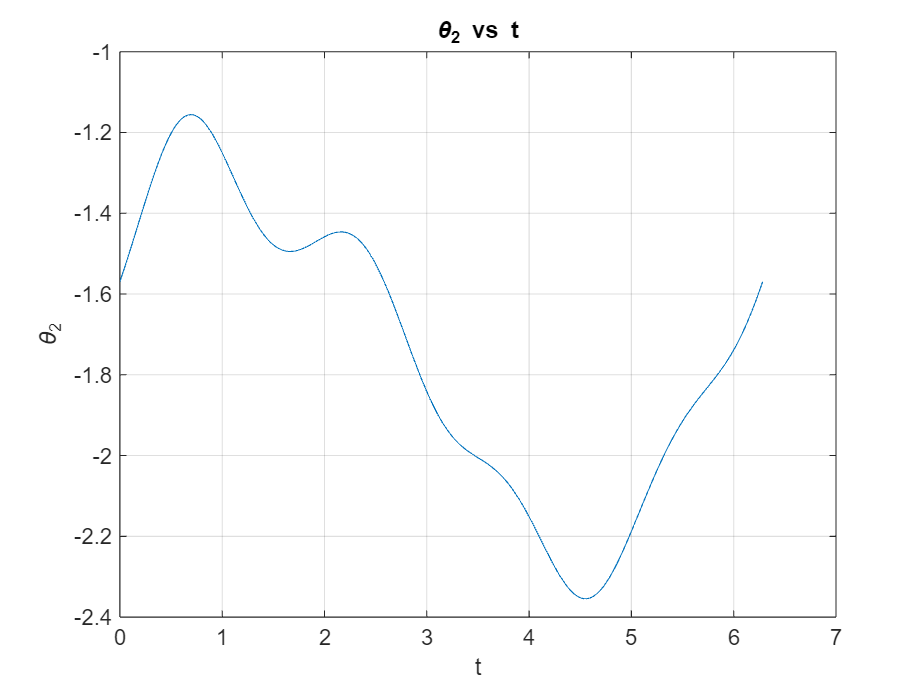

theta2 = b - 2*theta1;
theta2_values = double(subs(theta2, t, t_values));
plot(t_values, theta2_values);
xlabel('t');
ylabel('\theta_2');
title('\theta_2 vs t');
grid on;

**Velocidad **$\dot{\theta_1 }$

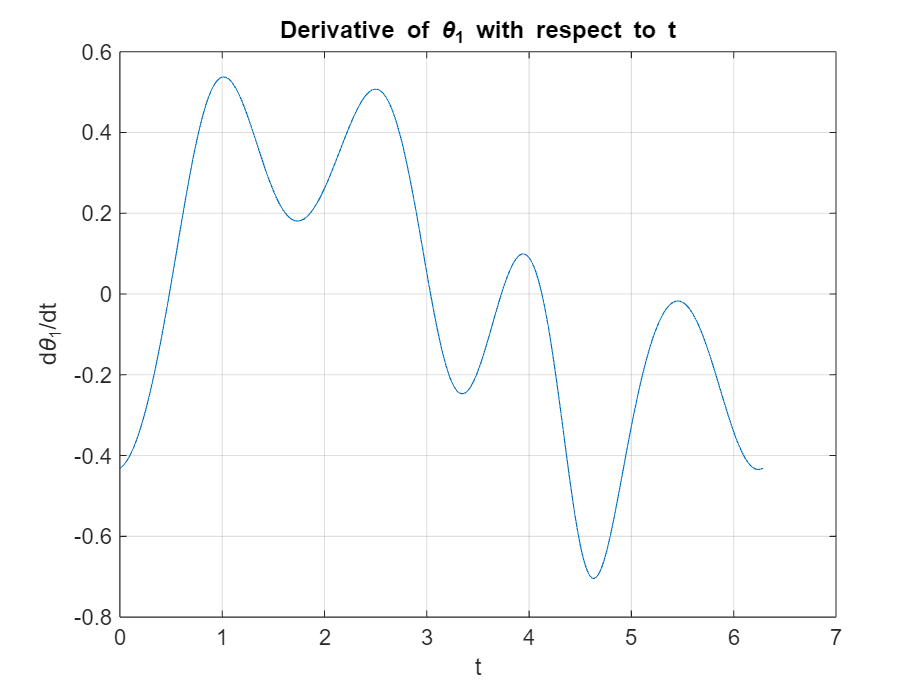

dt_theta1 = diff(theta1,t);
dt_theta1_values = double(subs(dt_theta1, t, t_values));
plot(t_values, dt_theta1_values);
xlabel('t');
ylabel('d\theta_1/dt');
title('Derivative of \theta_1 with respect to t');
grid on;

**Velocidad **$\dot{\theta_2 }$

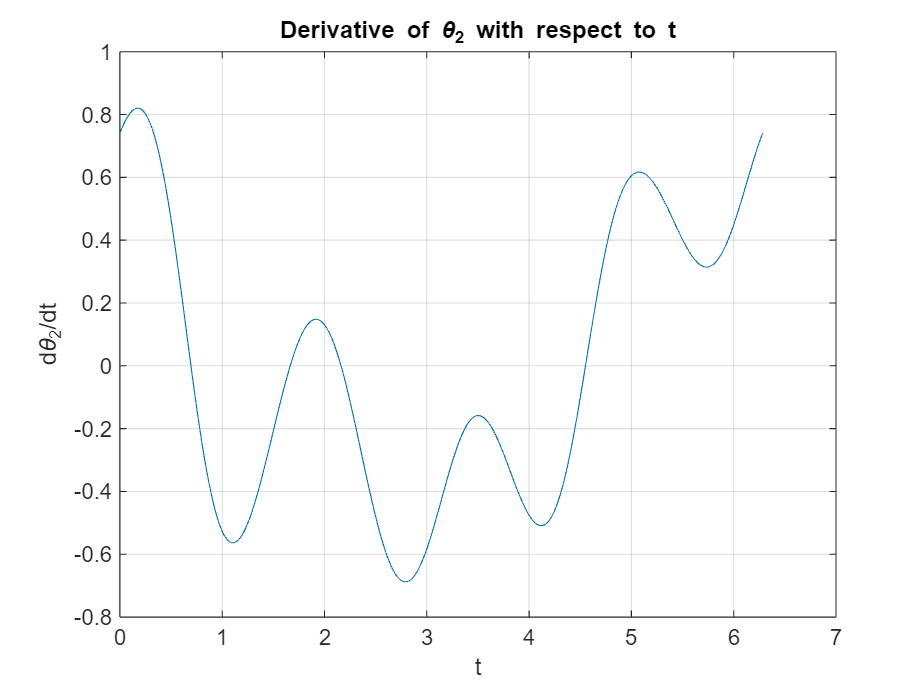

dt_theta2 = diff(theta2,t);
dt_theta2_values = double(subs(dt_theta2, t, t_values));
plot(t_values, dt_theta2_values);
xlabel('t');
ylabel('d\theta_2/dt');
title('Derivative of \theta_2 with respect to t');
grid on;

**Aceleración **$\ddot{\theta_1 }$

dt2_theta1 = diff(theta1,t,2);

dt2_theta1_values = double(subs(dt2_theta1, t, t_values));
plot(t_values, dt2_theta1_values);

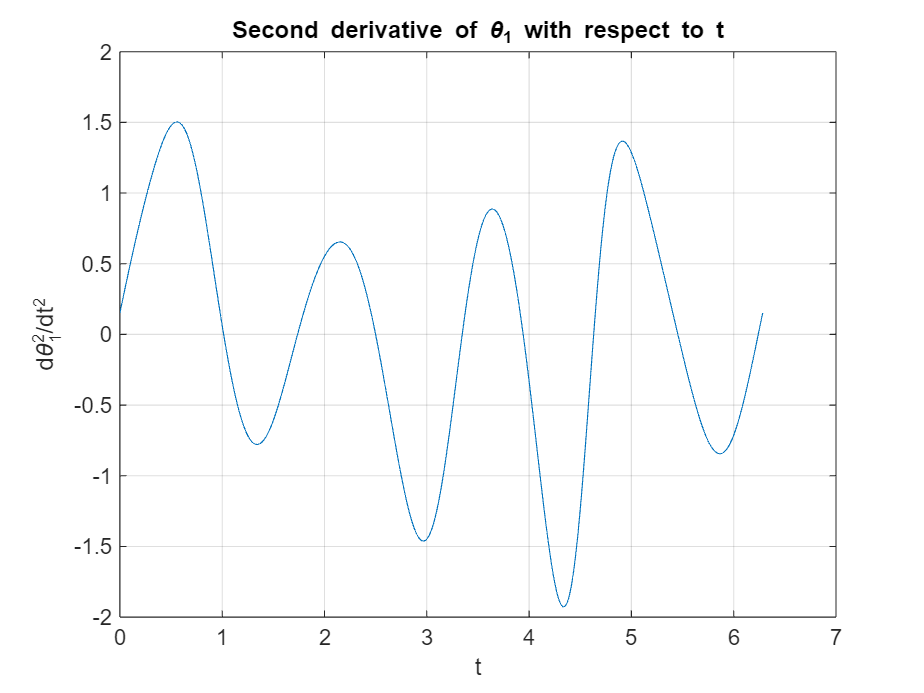

xlabel('t');
ylabel('d\theta_1^2/dt^2');
title('Second derivative of \theta_1 with respect to t');
grid on;

**Aceleración **$\ddot{\theta_2 }$

dt2_theta2 = diff(theta2,t,2);

dt2_theta2_values = double(subs(dt2_theta2, t, t_values));
plot(t_values, dt2_theta2_values);

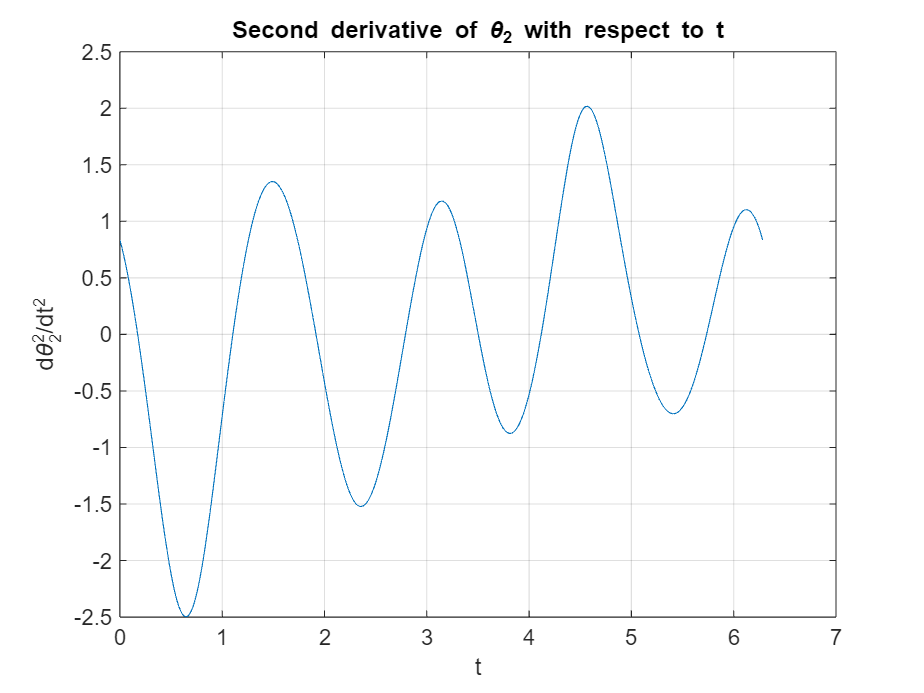

xlabel('t');
ylabel('d\theta_2^2/dt^2');
title('Second derivative of \theta_2 with respect to t');
grid on;

**Jerk **$\dot{\alpha_1 }$

dt3_theta1 = diff(theta1,t,3);
dt3_theta1_values = double(subs(dt3_theta1, t, t_values));
plot(t_values, dt3_theta1_values);

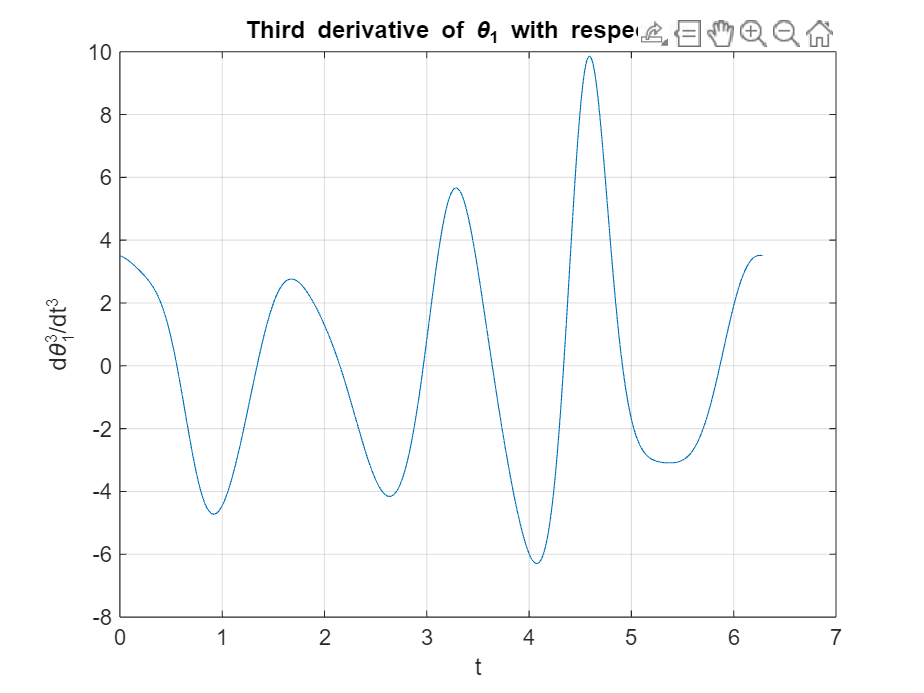

xlabel('t');
ylabel('d\theta_1^3/dt^3');
title('Third derivative of \theta_1 with respect to t');
grid on;

**Jerk **$\dot{\alpha_2 }$

dt3_theta2 = diff(theta2,t,3);
dt3_theta2_values = double(subs(dt3_theta2, t, t_values));
plot(t_values, dt3_theta2_values);

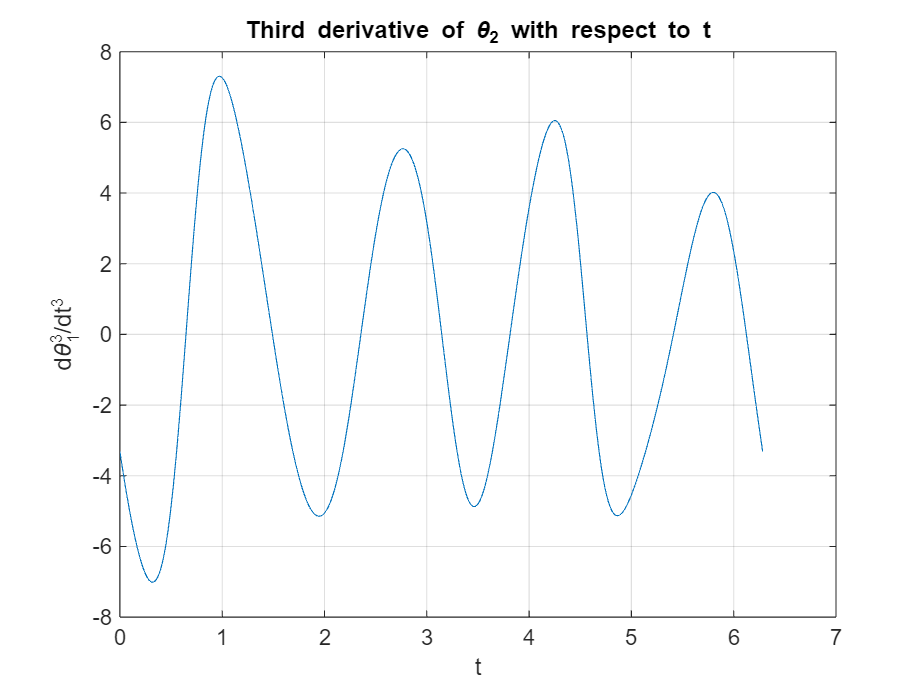

theta1_values =           1.73311036868725          1.72859679384562          1.72410393241587          1.71963580895213          1.71519643051092           1.7107897837588          1.70641983237922          1.70209051476515           1.6978057419814          1.69356939597849          1.68938532803786          1.68525735742638          1.68118927023653          1.67718481838704          1.67324771875785          1.66938165243164          1.66559026401388          1.66187716100223          1.65824591317572          1.65470005197396          1.65124306983617          1.64787841947006          1.64460951302086          1.64143972111084          1.63837237172081          1.63541074888536            1.632558091175          1.62981758993944          1.62719238728785          1.62468557378351          1.62230018583248          1.62003920274819          1.61790554347614          1.61590206296632           1.6140315481835          1.61229671374968          1.61070019721623          1.6092445539

theta2_values =          -1.56923382615911
         -1.56141975905306
         -1.55351775172704
         -1.54553197490149
          -1.5374668259124
         -1.52932692421199
         -1.52111710665124
         -1.51284242255394
         -1.50450812859052
         -1.49611968345752


xlabel('t');
ylabel('d\theta_1^3/dt^3');
title('Third derivative of \theta_2 with respect to t');
grid on;